# Program_01h.mlx: Harmonic and Damped Motion

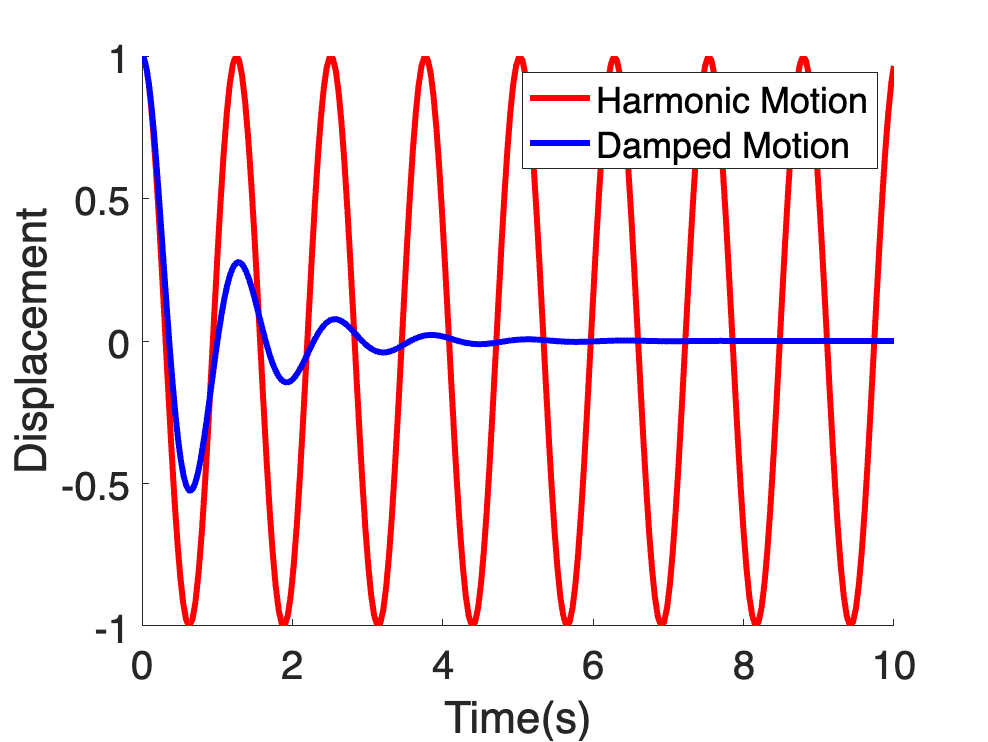

hold on
deq=@(t,x) [x(2);-25*x(1)];
[t,xa]=ode45(deq,[0,10],[1,0]);
plot(t,xa(:,1),'r','LineWidth',3)
deq=@(t,x) [x(2);-2*x(2)-25*x(1)];
[t,xb]=ode45(deq,[0,10],[1,0]);
plot(t,xb(:,1),'b','LineWidth',3);
legend('Harmonic Motion','Damped Motion')
xlabel('Time(s)');ylabel('Displacement');
set(gca,'FontSize',20);
hold off